X = (-6:0.2:6)';
Y = sinc(X) + 0.1.*rand(size(X));


out = [15 17 19];
Y(out) = 0.7+0.3*rand(size(out));
out = [41 44 46];
Y(out) = 1.5+0.2*rand(size(out));

model = initlssvm(X, Y, 'f', [], [], 'RBF_kernel');

costFun = 'crossvalidatelssvm';

model = tunelssvm(model, 'simplex', costFun, {10, 'mse';});


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         2413.3057
                                          [sig2]        0.18373
                                          F(X)=         0.12367
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   2413.3057     0.18372939

 Iteration   Func-count    min f(x)    log(gamma)    log(sig2)    Procedure

     1           3     1.236683e-01     7.7888        -1.6943      initial 
     2           5     1.236683e-01     7.7888        -1.6943      contract inside 
     3           7     1.236683e-01     7.7888        -1.6943      contract inside 
     4           9     1.236683e-01     7.788

Start Plotting...

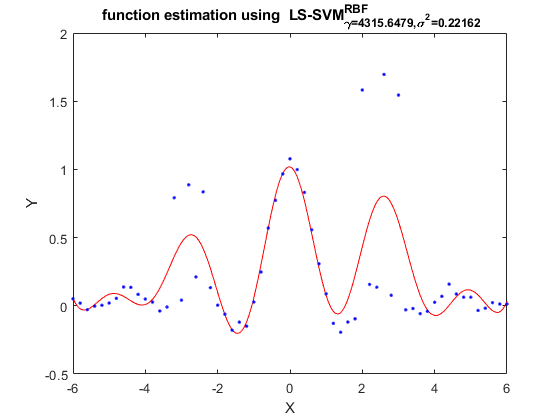

finished


plotlssvm(model);

model = initlssvm(X, Y, 'f' , [] , [] , 'RBF_kernel');

costFun = 'rcrossvalidatelssvm';

wFun = 'wmyriad' ;

model = tunelssvm(model , 'simplex' , costFun , {10 , 'mae' ;}, wFun);


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ****************************

**

***

**

***

**

***

**

model = robustlssvm(model);
plotlssvm(model);